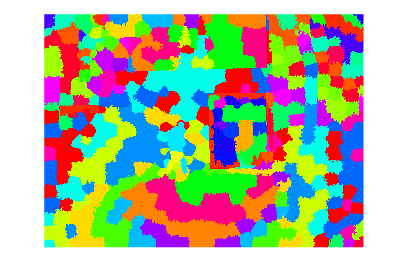

% 读取图像
image = imread('1.bmp');

% 将图像转换为一个矩阵
matrix = double(reshape(image, size(image, 1) * size(image, 2), size(image, 3)));

% 设置聚类的数量
k = 35;

% 使用K均值算法进行聚类
[idx, ~] = kmeans(matrix, k);

% 使用每个像素的索引重新塑造图像
idx = reshape(idx, size(image, 1), size(image, 2));

% 创建一个颜色映射
cmap = hsv(k); % 或者您可以选择其他如jet, hot等颜色映射方式

% 使用颜色映射显示图像
imshow(idx, cmap);